% --- MAIN SCRIPT FOR NONLINEAR BEAM-COLUMN ANALYSIS (RITZ METHOD) ---
% Includes both transverse (P) and axial (P_axial) loads.
% Solved with an EXPLICIT Newton-Raphson solver.
% NOW INCLUDES CALCULATION OF det(K_T) FOR STABILITY ANALYSIS.

clear; clc; close all;

%% 1. Define Symbolic Variables and Functions
syms x L E A I P P_axial real;
syms c2 c3 d1 d2 d3 d4 d5 real;

w_sym = c2*x^2 + c3*x^3;
u_sym = d1*x + d2*x^2 + d3*x^3 + d4*x^4 + d5*x^5;
dw_dx_sym = diff(w_sym, x);
d2w_dx2_sym = diff(w_sym, x, 2);
du_dx_sym = diff(u_sym, x);
eps0_sym = du_dx_sym + 0.5 * dw_dx_sym^2;
eps1_sym = -d2w_dx2_sym;
U_density = 0.5 * (E*A * eps0_sym^2 + E*I * eps1_sym^2);
U_total = int(U_density, x, 0, L);
W_ext = P * subs(w_sym, x, L) + P_axial * subs(u_sym, x, L);
Pi_total = U_total - W_ext;

%% 2. Generate the Residual Vector and Tangent Stiffness Matrix
coeffs = [c2, c3, d1, d2, d3, d4, d5];
fprintf('Generating the Residual and Tangent Stiffness expressions...\n');

Generating the Residual and Tangent Stiffness expressions...


R_expr = jacobian(Pi_total, coeffs)';
K_T_expr = jacobian(R_expr, coeffs);
fprintf('Converting expressions to MATLAB function handles...\n');

Converting expressions to MATLAB function handles...


vars = [{L, E, A, I, P, P_axial}, coeffs];
R_handle = matlabFunction(R_expr, 'Vars', vars);
K_T_handle = matlabFunction(K_T_expr, 'Vars', vars);

%% 3. Numerical Analysis Setup
L_val = 1.0; E_val = 210e9; b_val = 0.05; h_val = 0.05;
A_val = b_val * h_val; I_val = b_val * h_val^3 / 12;

P_max = 2e3;
P_axial_val = 0; % Compressive axial load to demonstrate stability loss

num_steps = 20;
load_steps = linspace(P_max/num_steps, P_max, num_steps);
axial_load_steps = linspace(P_axial_val/num_steps, P_axial_val, num_steps);

max_iter = 10;
tolerance = 1e-6;

%% 4. Solve with Incremental-Iterative Newton-Raphson
C = zeros(length(coeffs), 1);
C_history = zeros(length(coeffs), num_steps);
det_KT_history = zeros(1, num_steps); % <-- NEW: Array to store determinant history

for step = 1:num_steps
    current_load_P = load_steps(step);
    current_load_P_axial = axial_load_steps(step);
    
    fprintf('\nLoad Step %d/%d, P = %.2e N, P_axial = %.2e N\n', ...
        step, num_steps, current_load_P, current_load_P_axial);
    
    K_T = []; % Clear K_T from previous step
    for iter = 1:max_iter
        c_vals = num2cell(C');
        
        R = R_handle(L_val, E_val, A_val, I_val, current_load_P, current_load_P_axial, c_vals{:});
        K_T = K_T_handle(L_val, E_val, A_val, I_val, current_load_P, current_load_P_axial, c_vals{:});
        
        norm_R = norm(R);
        fprintf('  Iteration %d: Residual Norm = %.4e\n', iter, norm_R);
        
        if norm_R < tolerance
            fprintf('  Convergence achieved in %d iterations.\n', iter);
            break;
        end
        if iter == max_iter, warning('Max iterations reached.'); break; end

        delta_C = -K_T \ R;
        C = C + delta_C;
    end
    
    C_history(:, step) = C;
    
    % --- NEW: Calculate and store the determinant after convergence ---
    if ~isempty(K_T) % Ensure K_T was calculated in the loop
        det_KT_history(step) = det(K_T);
    end
    % --- END NEW SECTION ---
end


Load Step 1/20, P = 1.00e+02 N, P_axial = 0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 8.4950e-14


  Convergence achieved in 3 iterations.



Load Step 2/20, P = 2.00e+02 N, P_axial = -0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 7.7333e-14


  Convergence achieved in 3 iterations.



Load Step 3/20, P = 3.00e+02 N, P_axial = -0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 2.1523e-13


  Convergence achieved in 3 iterations.



Load Step 4/20, P = 4.00e+02 N, P_axial = -0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 7.3741e-13


  Convergence achieved in 3 iterations.



Load Step 5/20, P = 5.00e+02 N, P_axial = -0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 1.0450e-12


  Convergence achieved in 3 iterations.



Load Step 6/20, P = 6.00e+02 N, P_axial = -0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 2.5091e-12


  Convergence achieved in 3 iterations.



Load Step 7/20, P = 7.00e+02 N, P_axial = -0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 1.6969e-12


  Convergence achieved in 3 iterations.



Load Step 8/20, P = 8.00e+02 N, P_axial = -0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 1.8820e-12


  Convergence achieved in 3 iterations.



Load Step 9/20, P = 9.00e+02 N, P_axial = -0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 4.2851e-12


  Convergence achieved in 3 iterations.



Load Step 10/20, P = 1.00e+03 N, P_axial = -0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 3.4352e-12


  Convergence achieved in 3 iterations.



Load Step 11/20, P = 1.10e+03 N, P_axial = 0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 5.4443e-12


  Convergence achieved in 3 iterations.



Load Step 12/20, P = 1.20e+03 N, P_axial = 0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 4.0470e-12


  Convergence achieved in 3 iterations.



Load Step 13/20, P = 1.30e+03 N, P_axial = 0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 4.8133e-12


  Convergence achieved in 3 iterations.



Load Step 14/20, P = 1.40e+03 N, P_axial = 0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 5.6089e-12


  Convergence achieved in 3 iterations.



Load Step 15/20, P = 1.50e+03 N, P_axial = 0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 1.0312e-11


  Convergence achieved in 3 iterations.



Load Step 16/20, P = 1.60e+03 N, P_axial = 0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6864e+01
  Iteration 3: Residual Norm = 1.5821e-11


  Convergence achieved in 3 iterations.



Load Step 17/20, P = 1.70e+03 N, P_axial = 0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6865e+01
  Iteration 3: Residual Norm = 1.5393e-11


  Convergence achieved in 3 iterations.



Load Step 18/20, P = 1.80e+03 N, P_axial = 0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6865e+01
  Iteration 3: Residual Norm = 3.1455e-11


  Convergence achieved in 3 iterations.



Load Step 19/20, P = 1.90e+03 N, P_axial = 0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6865e+01
  Iteration 3: Residual Norm = 2.9038e-11


  Convergence achieved in 3 iterations.



Load Step 20/20, P = 2.00e+03 N, P_axial = 0.00e+00 N


  Iteration 1: Residual Norm = 1.4142e+02
  Iteration 2: Residual Norm = 9.6865e+01
  Iteration 3: Residual Norm = 2.4679e-11


  Convergence achieved in 3 iterations.



%% 5. Post-Processing: Load-Deflection Plot
fprintf('\n--- Analysis Complete ---\n');


--- Analysis Complete ---


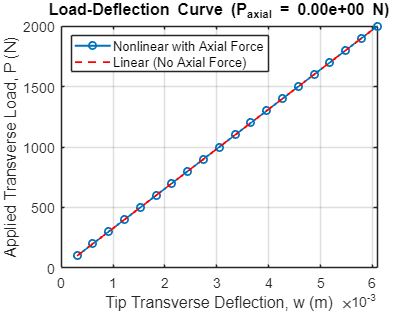

tip_deflections = zeros(1, num_steps);
for i = 1:num_steps
    c2_val = C_history(1, i);
    c3_val = C_history(2, i);
    tip_deflections(i) = c2_val * L_val^2 + c3_val * L_val^3;
end

figure('Name', 'Load-Deflection with Axial Force');
plot(tip_deflections, load_steps, '-o', 'LineWidth', 1.5, 'DisplayName', 'Nonlinear with Axial Force');
hold on;
w_linear = (load_steps * L_val^3) / (3 * E_val * I_val);
plot(w_linear, load_steps, '--r', 'LineWidth', 1.5, 'DisplayName', 'Linear (No Axial Force)');
grid on;
title(sprintf('Load-Deflection Curve (P_{axial} = %.2e N)', P_axial_val));
xlabel('Tip Transverse Deflection, w (m)');
ylabel('Applied Transverse Load, P (N)');
legend('show', 'Location', 'NorthWest');
set(gca, 'FontSize', 12);

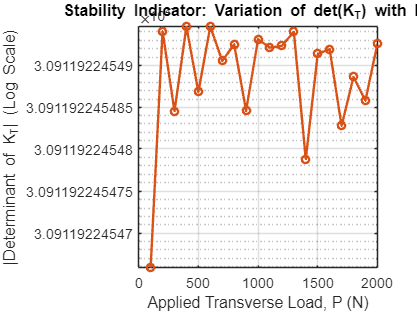


%% 6. Post-Processing: Final Deflected Shape Plot
% (Code from previous answer goes here)

%% --- NEW: Section 7: Plotting Determinant of Tangent Stiffness Matrix ---
figure('Name', 'Stability Analysis');

% Using semilogy for better visualization as determinant approaches zero
semilogy(load_steps, abs(det_KT_history), '-o', 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 2);

title('Stability Indicator: Variation of det(K_T) with Load');
xlabel('Applied Transverse Load, P (N)');
ylabel('|Determinant of K_T| (Log Scale)');
grid on;
set(gca, 'FontSize', 12);


% A decreasing trend indicates the system is losing stiffness and approaching
% an instability point (buckling), where the determinant would be zero.
% --- END NEW SECTION ---